load kernel-svm-2rings.mat
[d,n] = size(x);
K = RBF_kernel_2(x);
%% (a) Create a plot which shows how the sample-normalized cost 1/n g(ψ) evolves with iteration number t 
psi_t = SSGD_kernel(x,y);

psi_t =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

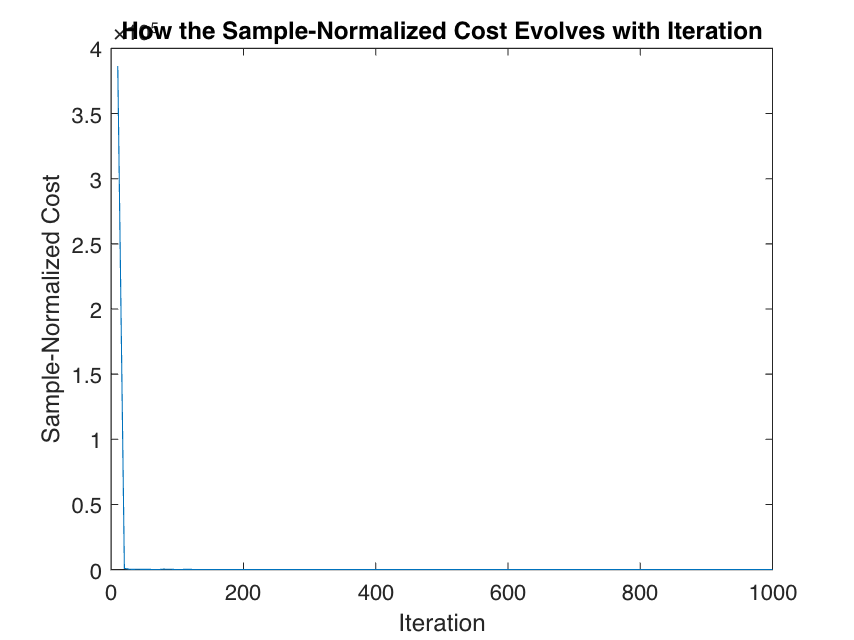

g_t = zeros(1,100);
for t = 1:100
    g_t(t) = (1/n) * cost(psi_t(:,t), K, y);
end

figure(1)
plot(10:10:1000,g_t)
title('How the Sample-Normalized Cost Evolves with Iteration')
xlabel('Iteration')
ylabel('Sample-Normalized Cost')

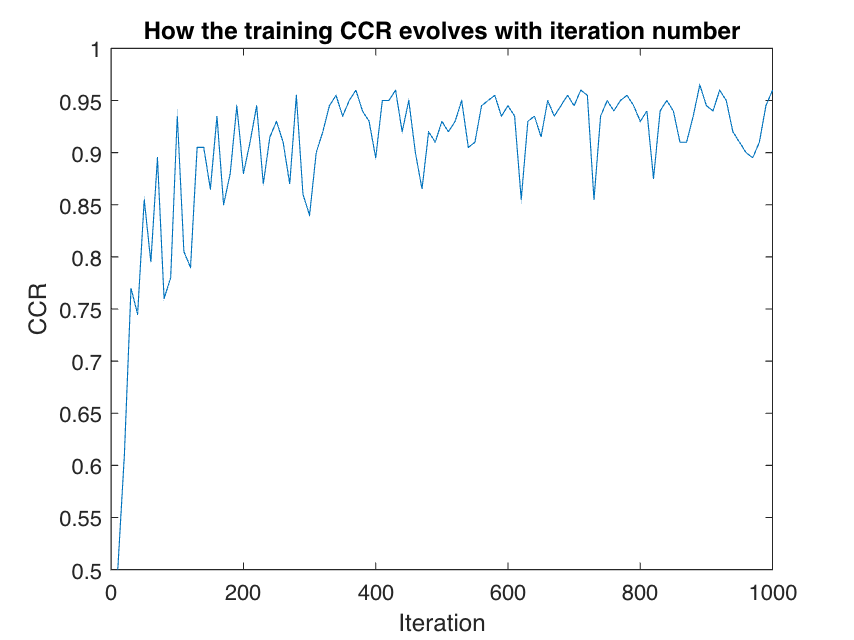

%% (b)
CCR_t = zeros(1,100);
[r c] = size(y);
for t = 1:100
    y_pred = zeros(r,c);
    for test = 1:n
        K_test = K(:,test);
        y_pred(test) = h_svm(psi_t(:,t),K_test);
    end
    CCR_t(t) = (sum(y == y_pred)) / n;
end
figure(2)
plot(10:10:1000,CCR_t)
title('How the training CCR evolves with iteration number')
xlabel('Iteration')
ylabel('CCR')

%% (c)
fprintf('The final training confusion matrix is\n');

The final training confusion matrix is


disp(confusionmat(y,y_pred))

    93     7
     1    99



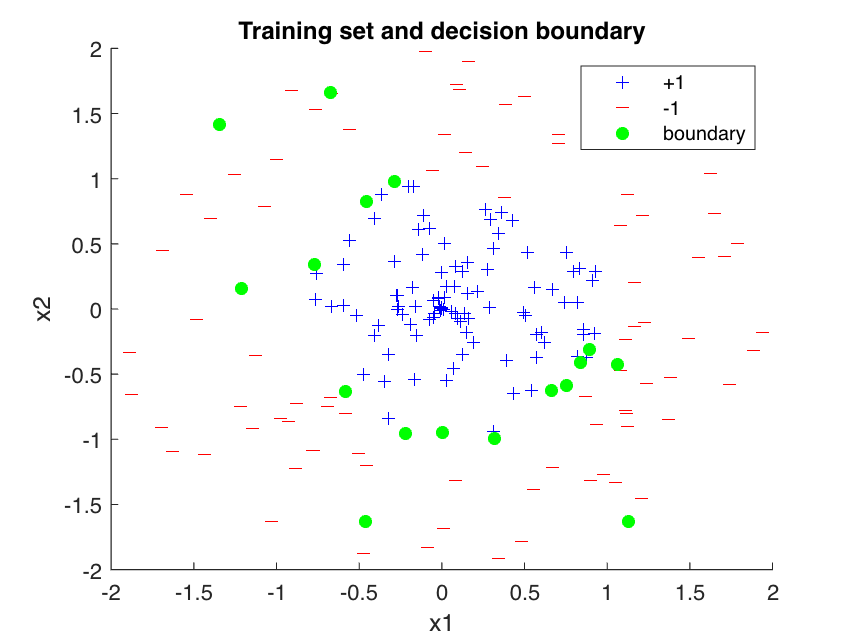

%% (d)
xpos = x(:,y == 1);
xneg = x(:,y == -1);
xpos_pred = x(:,y_pred == 1);
xneg_pred = x(:,y_pred == -1);
boundary = [];
for i = 1:n-1
    if(y_pred(i) ~= y_pred(i+1))
        boundary = [boundary x(:,i) x(:,i)];
    end
end
figure(3)
hold on
scatter(xpos(1,:),xpos(2,:),'b+')
scatter(xneg(1,:),xneg(2,:),'r_')
scatter(boundary(1,:),boundary(2,:),'filled','go')
%plot(boundary)
title('Training set and decision boundary')
xlabel('x1');
ylabel('x2');
legend('+1','-1','boundary')
hold off



%% 


load kernel-kmeans-2rings.mat
X = data';
k = 2;
Y = k_means_Kernel(X,k);

Unrecognized function or variable 'k_means_Kernel_3'.

figure(4)
gscatter(X(1,:),X(2,:),Y)
title('Cluster after Kernel K-means')
xlabel('x1')
ylabel('x2')
%% Use the RBF kernel with σ^2 = 0.16

function K = RBF_kernel_3(X)
    [d,n] = size(X);
    sigma = sqrt(0.16);
    K = zeros(n);
    first = -1/(2*(sigma^2));
    for u = 1:n
        for v = 1:n
            sec = (norm(X(:,u) - X(:,v))).^2;
            K(u,v) = exp(first * sec);
        end
    end
end
%% WCSS
function wcss = WCSS(e, alpha, K, y)
    [~,n] = size(K);
    wcss = 0;
    for j = 1:n
        wcss = wcss + (e(:,j)-alpha(:,y(j)))' * K * (e(:,j)-alpha(:,y(j)));
    end
end
%% 
function y = k_means_Kernel(X,k)
    [d,n] = size(X);
    y = ones(1,n);
    u = zeros(n,k);
    e = eye(n);
    K = RBF_kernel_3(X);
    iteration = 0;
    wcss_old = 0; wcss_new = 0;
    %initialize: cluster-mean coefficient vectors u` ∈ Rn, ` = 1, . . . , k, STOP = FALSE
    for l = 1:k
        %choose all coordinates if u1, u2 uniformly at random between 0 and 1
        ul = rand(n,1);
        %scale them so that they have uniy 1-norm
        u(:,l) = ul/norm(ul);
    end
    STOP = false;

    %repeat
    while(~STOP)
        iteration = iteration + 1;
        %update labels:
        for j = 1:n
            check1 = (e(:,j) - u(:,1))' * K * (e(:,j) - u(:,1));
            check2 = (e(:,j) - u(:,2))' * K * (e(:,j) - u(:,2));
            if(check1 < check2)
                y(j) = 1;
            else
                y(j) = 2;
            end
        end
        %update cluster-mean coefficient vectors:
        for l = 1:k
            yl = (y == l);
            nl = sum(yl);
            if nl ~= 0
                sec = 0;
                for j = 1:n
                    sec = sec + (e(:,j) * (y(j) == l));
                end
                u(:,l) = (1/nl) * sec;
                %u(:,l) = (1/nl) * sum(e(:,yl),2);
            else
                u(:,l) = zeros(n,1);
            end
        end
        %check stop
        if(iteration > 50)
            STOP = true;
        end
        wccs_old = wcss_new;
        wcss_new = WCSS(e, u, K, y);
        if(wcss_old == wcss_new)
            STOP = true;
        end
        
    end
end

function K = RBF_kernel_2(X)
    sigma = 0.5;
    [~,n] = size(X);
    K = zeros(n);
    for u = 1:n
        for v = 1:n
            first = -1/(2*(sigma^2));
            second = (norm(X(:,u) - X(:,v)))^2;
            K(u,v) = exp(first*second);
        end
    end
end
%% 
function psi_t = SSGD_kernel(X,Y)
    [d,n] = size(X);
    tmax = 1000;
    nC = 256;
    K = RBF_kernel_2(X);
    psi_t = zeros(n+1,100)
    %initialize
    psi = zeros(n+1,1);
    for t = 1:tmax
        s_t = 0.256/t;
        %choose sample index:
        j = randi(n,1);
        yj = Y(j);
        Kj_ext = [K(:,j);1];
        %compute subgradient
        v = conv2(K,[1,0;0,0]) * psi;
        if(yj*psi'*Kj_ext < 1)
            v = v - nC * yj * Kj_ext;
        end
        %update parameters:
        psi = psi - s_t * v;
        if(rem(t,10) == 0)
            psi_t(:,t/10) = psi;
        end
    end
end
%% 
function g = cost(psi, K, y)
    C = 256;
    n = length(y);
    f0 = (1/2) * psi' * conv2(K,[1,0;0,0]) * psi;
    g = f0;
    for j = 1:n
        f = C * hinge(y(j) * psi'* [K(:,j);1]);
        g = g + f;
    end
end
%% 
function out = hinge(t)
    if(0 > 1 - t)
        out = 0;
    else
        out = 1-t;
    end
end
%%
function label = h_svm(psi, K)
    label = sign(psi' * [K;1]);
end
